%%This script is used to calculate the power spectral density of the HRTF
%%database. This is done in order to equalise the database values to
%%account for the ear canals of the KEMAR. This will be done by calculating
%%the average PSD for each point on the database
clear


## Load HRTF database and obtain data in the required dimensions

dataset = load('ReferenceHRTF.mat');
hrtfData = dataset.hrtfData;
sourcePosition = dataset.sourcePosition(:,[1,2]);


## Separate Left and Right ear HRTFs

hrtfDataLeft = hrtfData(:,:,1);
hrtfDataRight = hrtfData(:,:,2);


## Compute FFT along the rows for each set of HRTF data

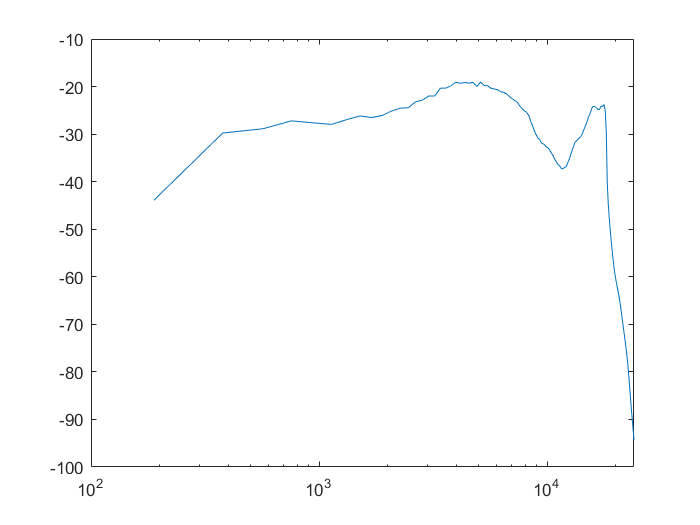

%testMatrix = hrtfDataLeft(1:2,:);
%x = fft(hrtfDataLeft);
x = fft(hrtfDataRight);
xSquared = abs(x.^2);
xSquared = xSquared(1:size(xSquared,1)/2,:);

%xLeft = xSquared(:,:,1);
%xRight = xSquared(:,:,2);

PSD = mean(xSquared,2);
%rightPSD = mean(xRight,2);

f = linspace(0,24000,length(PSD));

semilogx(f,10*log10(PSD));


% figure()
% plot(xLeft)
% 
% figure()
% plot(x(:,:,1))
% 
% figure()
% plot(hrtfDataLeft)

%plot(xSquared);
